clc;               
clear all;          
close all;
bdclose('all'); 

%%%%%%%%%%%%%%%%%%%%%%%%%% Initialisations des parametres  %%%%%%%%%%%%%%%%%%%%%%%%

%paramètres
epsilon = 0.00000001;
lambda_1 = 1;
lambda_2 = 1;
lambda_3 = 1;

% Reference 
u_r = 10;
v_r = 15;

% Temps final
tfinal = 20;

% Conditions initiales
u0 = 1;  v0 = 1; r0 = 1; 

%%%%%%%%%%%%%%%%%%%%%%%%%% Resolution des equations  %%%%%%%%%%%%%%%%%%%%%%%%%
disp('Simulation de sys');

Simulation de sys


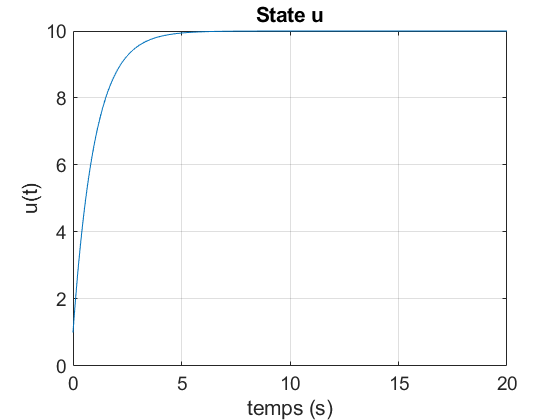

relTol = 1e-4;    absTol = 1e-7;  
options = odeset('RelTol', relTol, 'AbsTol', absTol);
[ts,Xs] = ode45(@dyn, [0 tfinal], [u0 v0 r0], options, lambda_1,lambda_2,lambda_3,u_r,v_r); 

%%%%%%%%%%%%%%%%%%%%%%%%%% Extraction des etats et commades %%%%%%%%%%%%%%%%%%%%%%%%

u = Xs(:,1);  v = Xs(:,2); r = Xs(:,3); 

du_r = gradient(u_r);
dv_r = gradient(v_r);
ddv_r = gradient(dv_r);

% calcul des commandes
tau_u = du_r -lambda_1.*(u-u_r)- v.*r;
tau_r = -(1./(u + epsilon)).*( ddv_r - lambda_2.*(v-v_r) - lambda_3.*(- u.*r - dv_r) + v.*(r.^2) + tau_u.*r);

%%%%%%%%%%%%%%%%%%%%%%%%%% Ploting %%%%%%%%%%%%%%%%%%%%%%%%
% control u
figure(1);
plot(ts,u); grid on; 
xlabel('temps (s)'); ylabel('u(t)');    
title('State u');

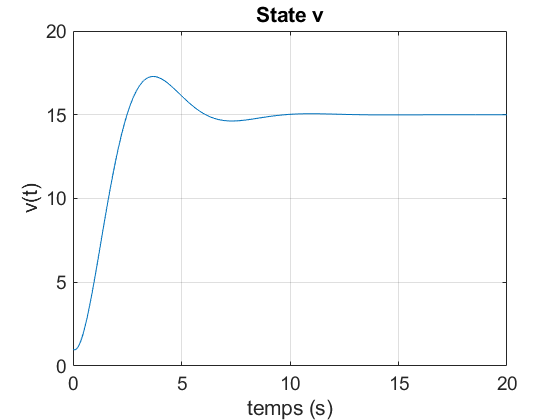


% speed v
figure(2);
plot(ts,v); grid on; 
xlabel('temps (s)'); ylabel('v(t)');    
title('State v');

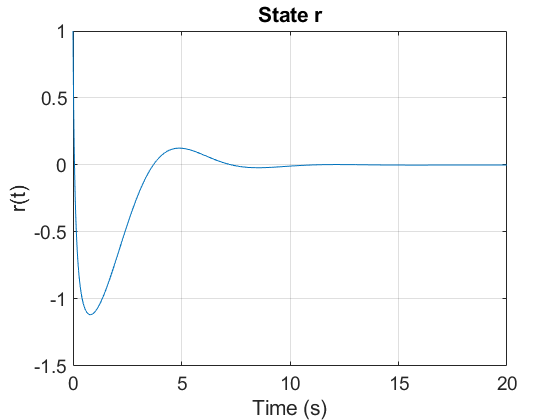


% speed r
figure(3);
plot(ts,r); grid on; 
xlabel('Time (s)'); ylabel('r(t)');    
title('State r');

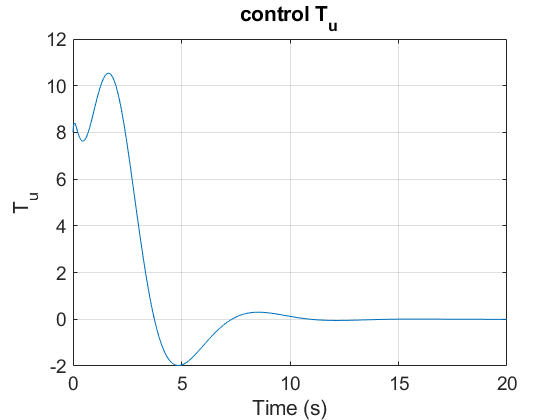


% commandes tau_u
figure(4);
plot(ts, tau_u); grid; 
xlabel('Time (s)'); ylabel('T_u');
title('control T_u');

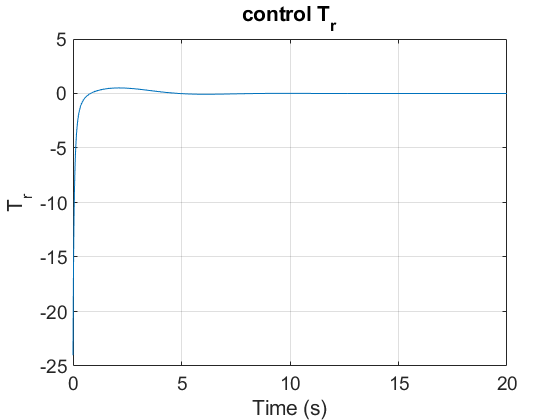


%commandes tau_r
figure(5);
plot(ts, tau_r); grid; 
xlabel('Time (s)'); ylabel('T_r');
title('control T_r');